## Data sampling for ID

### trim data

start_time = duration('00:00:00.148000');
end_time = duration('00:00:00.152000');

% Create a timerange object
ts_range = timerange(start_time, end_time);

% Index both pitch_in and elevator using the rows subscript
elevator_trim = pitch_in.pitch_in(ts_range,:) - elevator.elevator(ts_range,:)

elevator_trim = 0

throttle_trim = throttle_in.throttle_in(ts_range,:) - throttle.throttle(ts_range,:)

throttle_trim = 0

airspeed_trim = ind_airspeed.indicated_airspeed(ts_range,:)

airspeed_trim = single
33.8515

alt_trim = alt.alt(ts_range,:)

alt_trim = single
488.2813

pitch_rate_trim = q.q(ts_range,:)

pitch_rate_trim = 0.1897

alpha_trim = alpha.alpha(ts_range,:)

alpha_trim = single
0.7436

### step input

t_start = duration('00:00:00.148000');
t_end_s = duration('00:02:53.776000');
t_end_p = duration('00:04:53.776000');

% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_step = throttle.throttle(ts_range,:);
elevator_s_step = elevator.elevator(ts_range,:);
q_s_step = q.q(ts_range,:); 
aoa_s_step = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_step = throttle.throttle(ts_range,:);
elevator_p_step = elevator.elevator(ts_range,:);
vel_p_step = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_step = alt.alt(ts_range,:);

### doublet input

t_start = duration('00:00:00.148000');
t_end_s = duration('00:02:53.776000');
t_end_p = duration('00:04:53.776000');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_doublet = throttle.throttle(ts_range,:);
elevator_s_doublet = elevator.elevator(ts_range,:);
q_s_doublet = q.q(ts_range,:); 
aoa_s_doublet = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_doublet = throttle.throttle(ts_range,:);
elevator_p_doublet = elevator.elevator(ts_range,:);
vel_p_doublet = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_doublet = alt.alt(ts_range,:);

### sine sweep input

t_start = duration('00:00:00.148000');
t_end_s = duration('00:02:53.776000');
t_end_p = duration('00:04:53.776000');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_sine = throttle.throttle(ts_range,:);
elevator_s_sine = elevator.elevator(ts_range,:);
q_s_sine = q.q(ts_range,:); 
aoa_s_sine = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_sine = throttle.throttle(ts_range,:);
elevator_p_sine = elevator.elevator(ts_range,:);
vel_p_sine = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_sine = alt.alt(ts_range,:);

## System ID script - step

iodelay = 0;
u1 = throttle_s_step;
u2 = elevator_s_step;
u3 = throttle_p_step;
u4 = elevator_p_step;
y3 = q_s_step - pitch_rate_trim;
y1 = double(vel_p_step - airspeed_trim);
y4 = double(aoa_s_step - alpha_trim);
y5 = double(alt_p_step - alt_trim);

### MIMO identification - short period mode

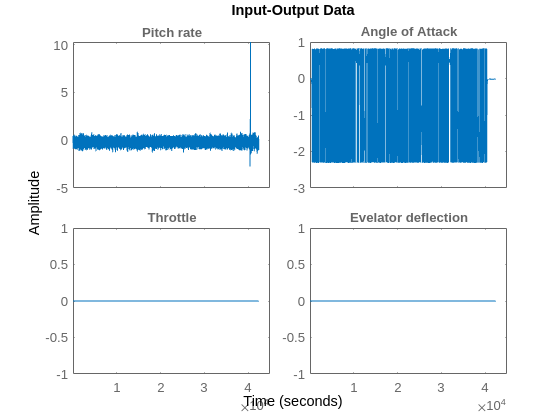

u = [u1 u2];
y = [y3 y4];
np = [2 2; 2 2];
nz = [1 2; 1 1];
data = iddata(y,u);
set(data,'InputName',{'Throttle','Evelator deflection'},'OutputName',{'Pitch rate', 'Angle of Attack'})
plot(data)

sys1= tfest(data,np,nz,iodelay);

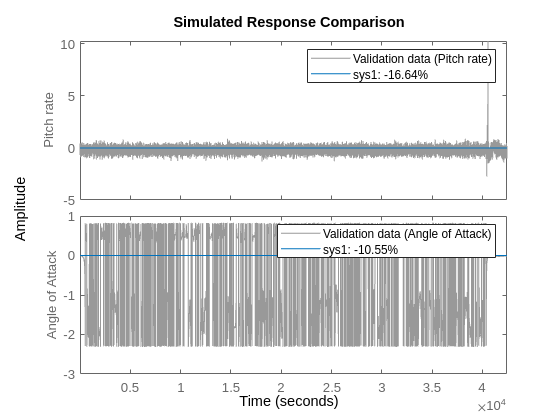

compare(data,sys1)

### MIMO identification - Phugoid mode

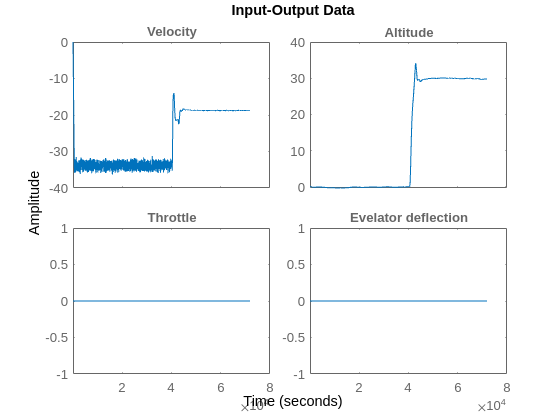

u = [u3 u4];
y = [y1 y5];
np = [3 2; 3 3];
nz = [1 1; 2 2];
data = iddata(y,u);
set(data,'InputName',{'Throttle','Evelator deflection'},'OutputName',{'Velocity', 'Altitude'});
plot(data)

sys2= tfest(data,np,nz,iodelay);

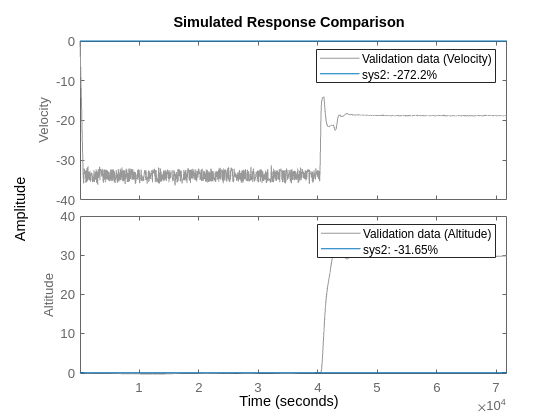

compare(data,sys2)

### system identified

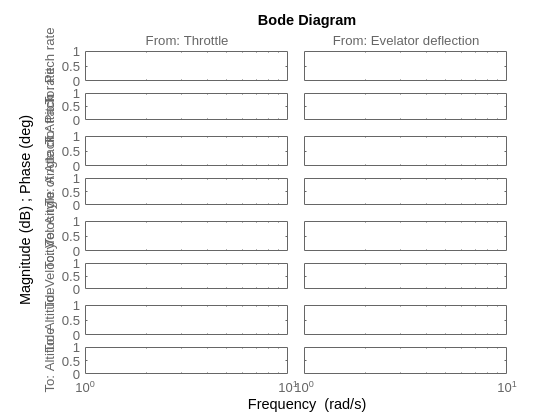

G1 = tf([sys1; sys2]);  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height
bode(G1)

## System ID script - doublet

iodelay = 0;
u1 = throttle_s_doublet;
u2 = elevator_s_doublet;
u3 = throttle_p_doublet;
u4 = elevator_p_doublet;
y1 = double(vel_p_doublet - airspeed_trim);
y3 = q_s_doublet - pitch_rate_trim;
y4 = double(aoa_s_doublet - alpha_trim);
y5 = double(alt_p_doublet - alt_trim);

### MIMO identification - short period mode

u = [u1 u2];
y = [y3 y4];
np = [2 2; 2 2];
nz = [1 2; 1 1];
data = iddata(y,u);
set(data,'InputName',{'Throttle','Evelator deflection'},'OutputName',{'Pitch rate', 'Angle of Attack'})
plot(data)

sys1= tfest(data,np,nz,iodelay);

compare(data,sys1)

### MIMO identification - Phugoid mode

u = [u3 u4];
y = [y1 y5];
np = [3 2; 3 3];
nz = [1 1; 2 2];
data = iddata(y,u);
set(data,'InputName',{'Throttle','Evelator deflection'},'OutputName',{'Velocity', 'Altitude'});
plot(data)

sys2= tfest(data,np,nz,iodelay);

compare(data,sys2)

### system identified

G2 = tf([sys1; sys2]);  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height
bode(G2)

## System ID script - sine sweep

iodelay = 0;
u1 = throttle_s_sine;
u2 = elevator_s_sine;
u3 = throttle_p_sine;
u4 = elevator_p_sine;
y1 = double(vel_p_sine - airspeed_trim);
y3 = q_s_sine - pitch_rate_trim;
y4 = double(aoa_s_sine - alpha_trim);
y5 = double(alt_p_sine - alt_trim);

### MIMO identification - short period mode

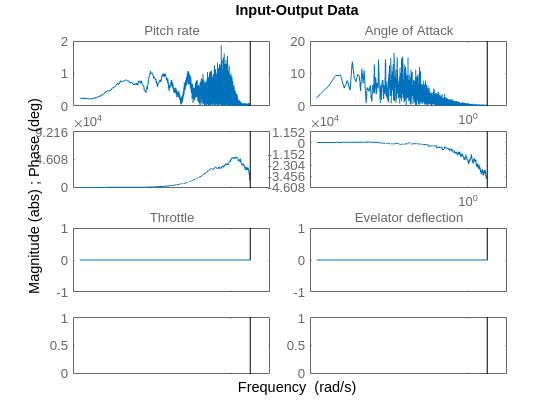

u = [u1 u2];
y = [y3 y4];
np = [2 2; 2 2];
nz = [1 2; 1 1];
data = iddata(y,u);
data = fft(data);
set(data,'InputName',{'Throttle','Evelator deflection'},'OutputName',{'Pitch rate', 'Angle of Attack'})
plot(data)

sys1= tfest(data,np,nz,iodelay);

sys1 =
  From input "Throttle" to output...
                      1.266e-15
   Pitch rate:  ---------------------
                s^2 + 6.285 s + 9.876
 
                           1.266e-15
   Angle of Attack:  ---------------------
                     s^2 + 6.285 s + 9.876
 
  From input "Evelator deflection" to output...
   Pitch rate:  0
 
                           1.266e-15
   Angle of Attack:  ---------------------
                     s^2 + 6.285 s + 9.876
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [2 0;2 2]   Number of zeros: [1 2;1 1]
   Number of free coefficients: 16
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                                                                                                                                                                                                                                                            

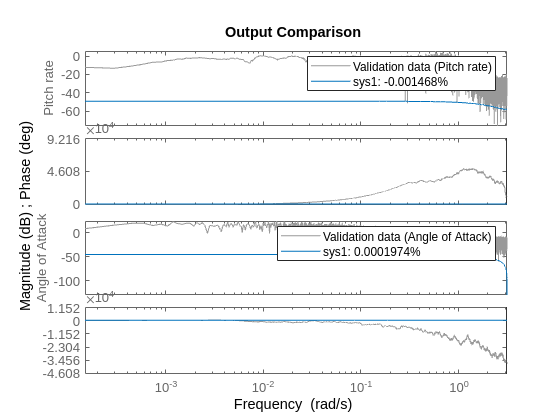

compare(data,sys1)

### MIMO identification - Phugoid mode

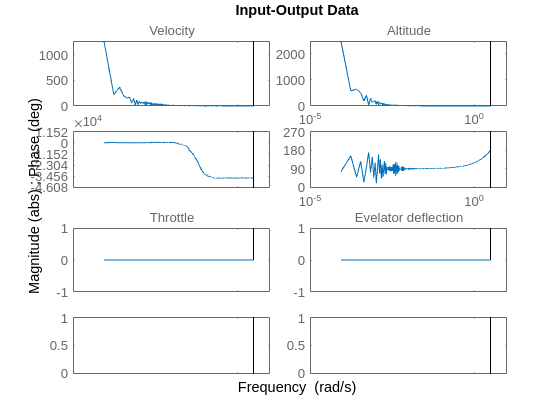

u = [u3 u4];
y = [y1 y5];
np = [3 2; 3 3];
nz = [1 1; 2 2];
data = iddata(y,u);
data = fft(data);
set(data,'InputName',{'Throttle','Evelator deflection'},'OutputName',{'Velocity', 'Altitude'})
plot(data)

sys2= tfest(data,np,nz,iodelay);

sys2 =
  From input "Throttle" to output...
                   4.386e-15 s - 6.121e-30
   Velocity:  ---------------------------------
              s^3 + 9.428 s^2 + 29.63 s + 31.04
 
                   4.386e-15 s - 6.121e-30
   Altitude:  ---------------------------------
              s^3 + 9.428 s^2 + 29.63 s + 31.04
 
  From input "Evelator deflection" to output...
                    1.266e-15
   Velocity:  ---------------------
              s^2 + 6.285 s + 9.876
 
                   4.386e-15 s - 6.121e-30
   Altitude:  ---------------------------------
              s^3 + 9.428 s^2 + 29.63 s + 31.04
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [3 2;3 3]   Number of zeros: [1 1;2 2]
   Number of free coefficients: 21
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                                                                                                         

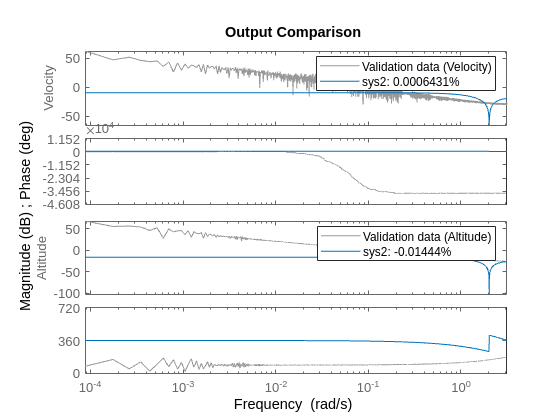

compare(data,sys2)

### system identified

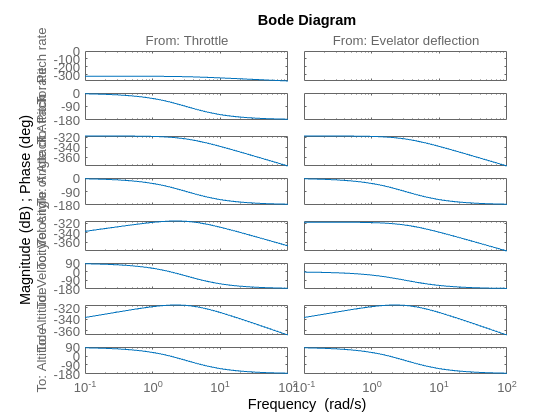

G3 = tf([sys1; sys2]);  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height
bode(G3)